# Lorenz: saved-checkpoint evaluation

This Live Script inspects interrupted training read-only. Validation is the default so unfinished models can be monitored without leaking held-out test information into scientific decisions.

clearvars; close all; clc;

## Locate the publication code

checkpoint_directory = fileparts(mfilename('fullpath'));
evaluation_directory = fileparts(checkpoint_directory);
repository_root = fileparts(evaluation_directory);
addpath(repository_root, checkpoint_directory);

## Choose the checkpoint family

Use the same profile and scientific overrides as training. Missing requested seeds are reported and skipped.

seeds = 1:3;
profile = "main";             % main, full_rank, spsa, or neuron_sweep
overrides = struct();          % reproduce scientific training overrides here

## Choose monitoring and export behaviour

display_options = struct();
display_options.checkpoint_files = strings(0,1); % optional explicit full paths
display_options.skip_missing = true;
display_options.assessment_split = "validation"; % change to "test" for held-out testing
display_options.checkpoint_state = "current";      % current or best validation state
display_options.run_recurrent_ablation = true;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'checkpoint_evaluation', 'lorenz');

## Run the complete selected-split evaluation and plots


BANFF saved-checkpoint evaluation: lorenz (main profile)
Assessment split: validation | checkpoint state for full diagnostics: current

Loaded seed 1: epoch 10815/60000 (18.02%), best epoch 2900


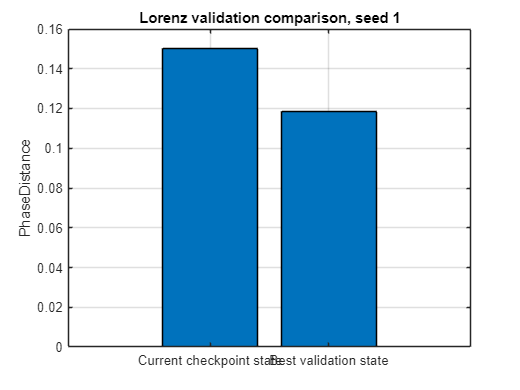


Checkpoint progress and independently recomputed validation performance
      Task      Seed    CheckpointEpoch    TotalEpochs    PercentComplete    BestEpoch    ValidationMetric    CurrentValidation    BestStateValidation                                                                                                                   CheckpointFile                                                                                                               
    ________    ____    _______________    ___________    _______________    _________    ________________    _________________    ___________________    ___________________________________________________

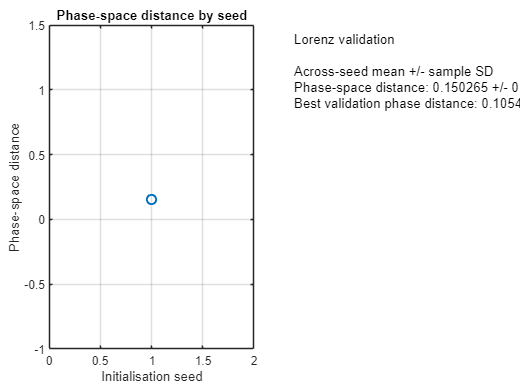

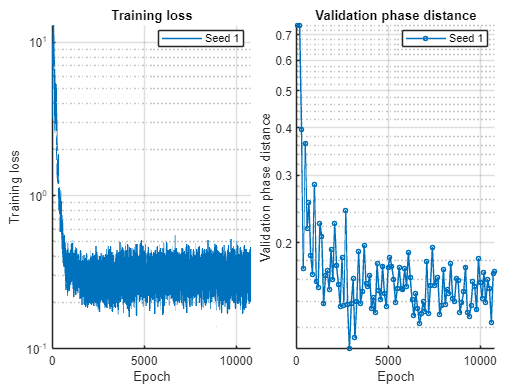

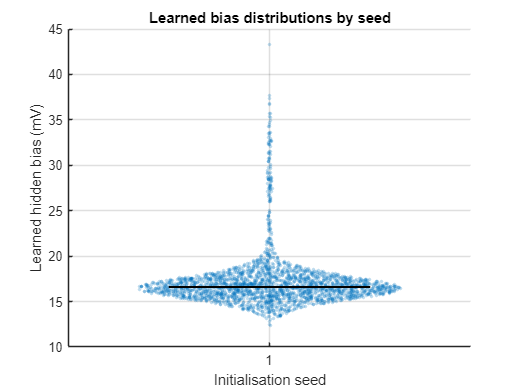

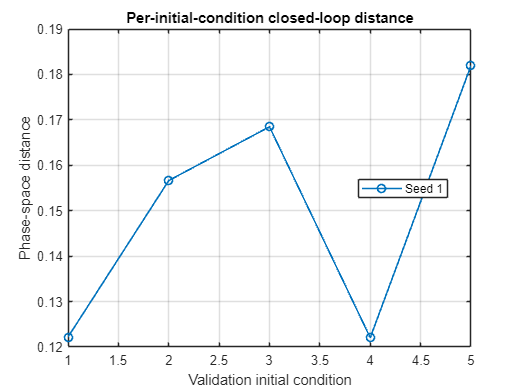

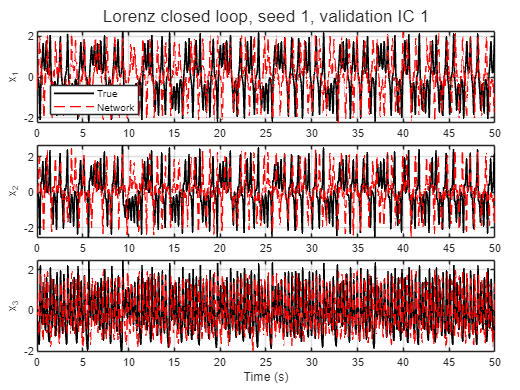

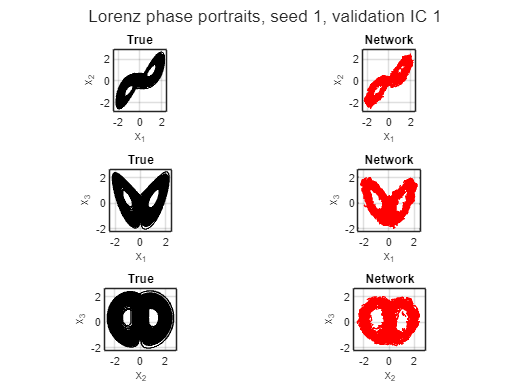

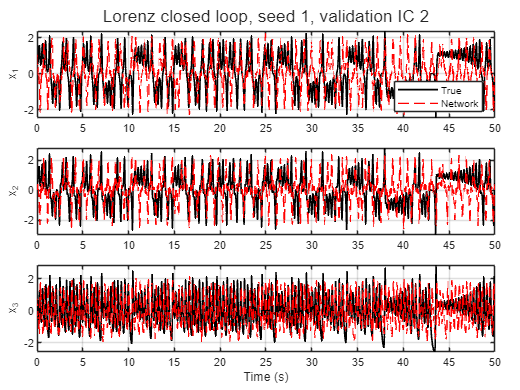

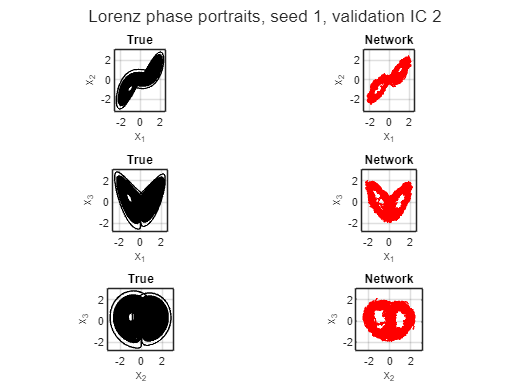

Representative dynamics seed 1: 13.28% active, 86.72% silent neurons; 1475762 spikes.
Inverse-ISI distribution pools 6675917 within-trajectory intervals from all 32000 neurons and all 5 validation initial conditions.
Exact full-validation DS current magnitudes (scored interval; warmup excluded)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    

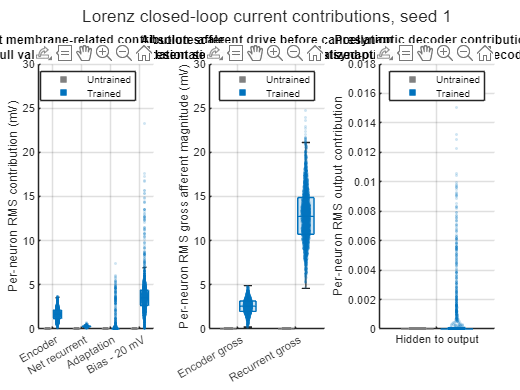

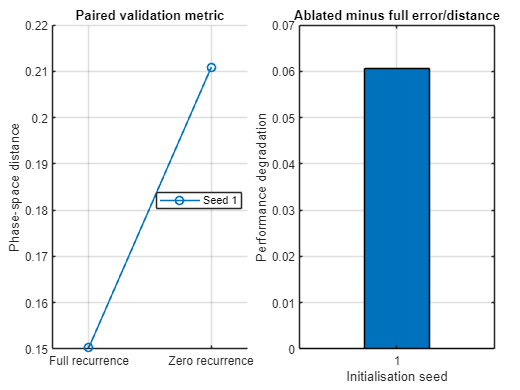

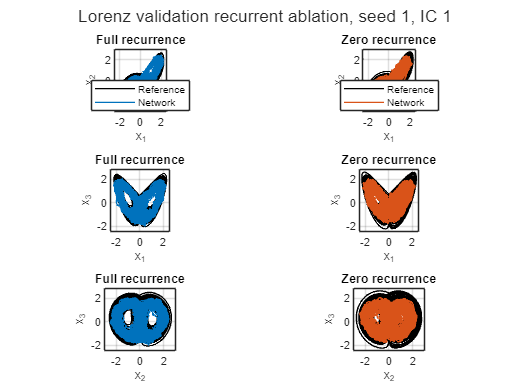

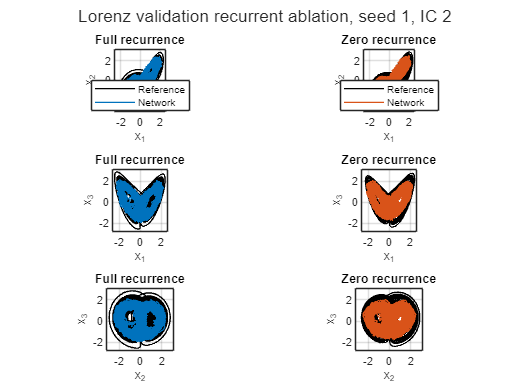

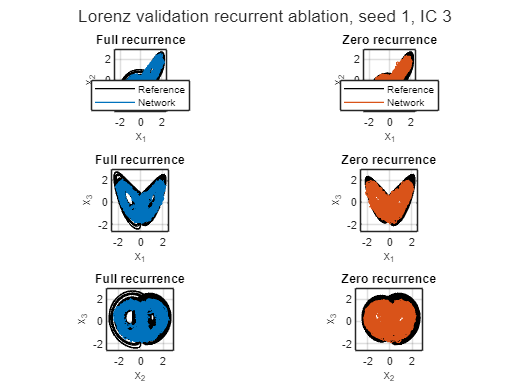

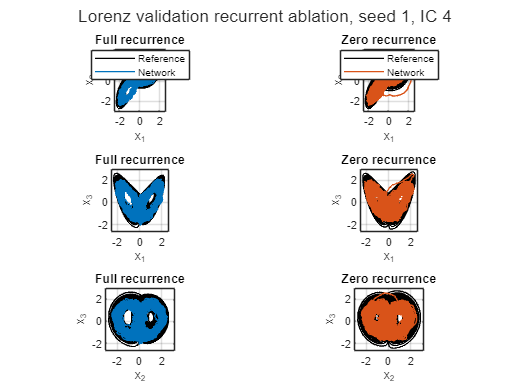

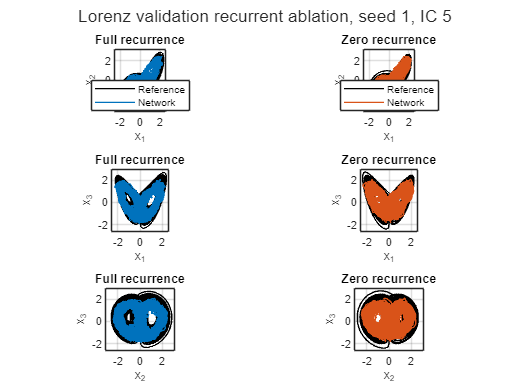

report = banff_evaluate_checkpoints("lorenz", seeds, profile, overrides, display_options);

## Machine-readable checkpoint summary

report.summary_table

ans = 1×10 table
      Task      Seed    CheckpointEpoch    TotalEpochs    PercentComplete    BestEpoch    ValidationMetric    CurrentValidation    BestStateValidation                                                                                                                   CheckpointFile                                                                                                               
    ________    ____    _______________    ___________    _______________    _________    ________________    _________________    ___________________    ___________________________________________________________________________________________________________

report.seed_table

ans = 1×4 table
    Seed    PhaseDistance    BestValidationPhaseDistance    ValidationInitialConditions
    ____    _____________    ___________________________    ___________________________

     1         0.15027                 0.10543                           5             


report.metric_summary_table

ans = 2×4 table
               Metric                 Mean      SampleSD    FiniteN
    _____________________________    _______    ________    _______

    "PhaseDistance"                  0.15027       0           1   
    "BestValidationPhaseDistance"    0.10543       0           1   


report.recurrent_ablation

ans = 1×7 table
    Seed        Metric         FullRecurrence    ZeroRecurrence    Degradation    FullLoss    ZeroRecurrenceLoss
    ____    _______________    ______________    ______________    ___________    ________    __________________

     1      "PhaseDistance"       0.15027           0.21086         0.060592        NaN              NaN        


report.missing_files

ans = 2×1 string array
    "C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\BANFF_SNN_pub\outputs\models\lorenz_eprop_low_rank_hard_spike_N32000_cfga9f0b40d77bb_seed002_checkpoint.mat"
    "C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\BANFF_SNN_pub\outputs\models\lorenz_eprop_low_rank_hard_spike_N32000_cfga9f0b40d77bb_seed003_checkpoint.mat"
